# Controllo della temperatura di una casa

## Descrizione del problema

L'obiettivo del progetto è regolare la temperatura di una casa utilizzando un controllore MPC. Si ipotizza che la casa non condivida alcun muro esterno con altre abitazioni, che i ﬂussi d'aria tra le stanze della casa siano trascurabili e che il riscaldamento della casa sia affidato a tre termosifoni, uno per ogni stanza. La pianta della casa in oggetto è mostrata nella figura seguente:

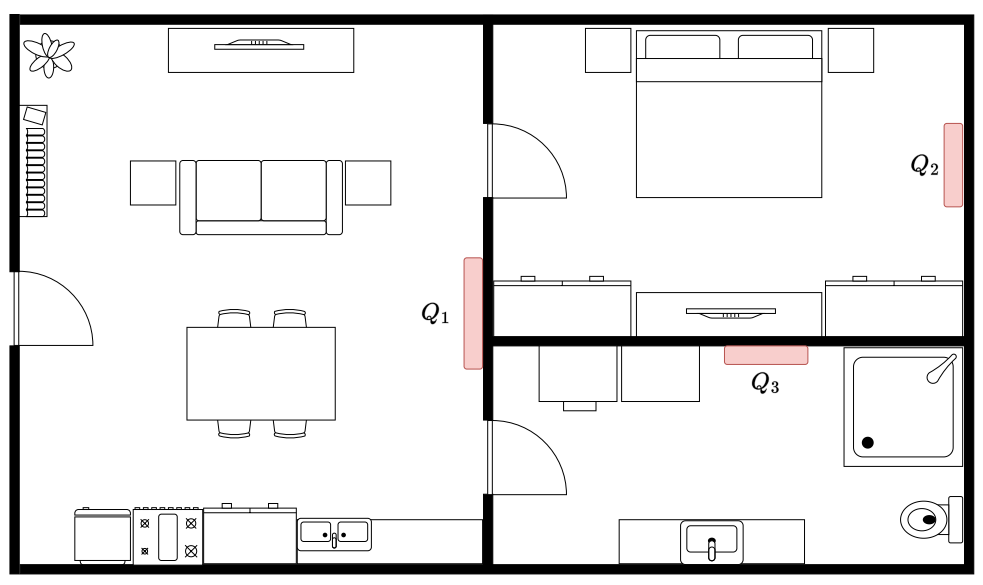

Figura 1: Planimetria della casa.

La dinamica della temperatura all’interno della casa è deﬁnita dalle equazioni seguenti:

$\begin{cases}
C_1\dot{T}_1(t) = Q_1(t) - k_{1,2}(t)(T_1(t)-T_2(t)) - k_{1,3}(t)(T_1(t)-T_3(t)) - k_{ext}(T_1(t)-T_{ext})\\
C_2\dot{T}_2(t) = Q_2(t) + k_{1,2}(t)(T_1(t)-T_2(t)) - k_{2,3}(t)(T_2(t)-T_3(t)) - k_{ext}(T_2(t)-T_{ext})\\
C_3\dot{T}_3(t) = Q_3(t) + k_{1,3}(t)(T_1(t)-T_3(t)) + k_{2,3}(t)(T_2(t)-T_3(t)) - k_{ext}(T_3(t)-T_{ext})\\
\dot{Q}_1 = (Q_{1,r}(t)-Q_1(t))/\tau_1 \\
\dot{Q}_2 = (Q_{2,r}(t)-Q_2(t))/\tau_2\\
\dot{Q}_3 = (Q_{3,r}(t)-Q_3(t))/\tau_3
\end{cases}$  con $k_{i,j} ={\bar{k} }_{i,j} +\frac{4}{1+e^{-0\ldotp 5{\left\|T_i \left(t\right)-T_j \left(t\right)\right\|}_2 } }$

Il significato delle grandezze presenti nelle precedenti equazioni è il seguente:

- $T_i\;[K]$ è la temperatura della i-esima stanza;

- $T_{ext}\;[K]$ è la temperatura esterna, ipotizzata costante.

- $C_i\;[J/s]$ è la capacità termica della i-esima stanza;

- $k_{i,j}\;[W/K]$ è un parametro che regola lo scambio di calore tra l’i-esima e la j-esima stanza;

- $k_{ext}\;[W/K]$ è un parametro che regola lo scambio di calore tra le stanze della casa e l’esterno;

- $Q_i\;[W]$ è la potenza termica dell’i-esimo termosifone;

- $Q_{i,r}\;[W]$ è la potenza termica di riferimento dell’i-esimo termosifone;

- $\tau_i\;[s]$ è la costante di tempo dell’i-esimo termosifone. 

I parametri noti sono riportati nella tabella seguente:


$$\matrix{
\textbf{Parametro} & \textbf{Valore} & \textbf{Unità}    \cr
C_1 		& 6800 		& J/s	        \cr
C_2			& 5600		& J/s		\cr
C_3	        	& 5100 		& J/s		\cr
\bar{k}_1 		& 15 		& W/K	        \cr
\bar{k}_2		& 20	         	& W/K		\cr
\bar{k}_3	       	& 15 		& W/K		\cr
k_{ext}	       	& 8 	        	& W/K		\cr
T_{ext}	       	& 278        	& K    		\cr
\tau_1 		& 400 		& s	                \cr
\tau_2		& 450		& s		        \cr
\tau_3        	& 450 		& s	        	\cr
}$$


Tabella 1: Parametri noti del sistema in esame.

La potenza erogata dai tre termosifoni è non-negativa e mai superiore ai 150W, mentre la temperatura all’interno delle tre stanze non deve mai scendere al di sotto dei 286K.

Gli ingressi controllati del sistema sono le potenze di riferimento dei tre termosifoni, $Q_{i,r}$, $i \in \{1,2,3\}$.

L’obiettivo del lavoro è progettare un controllore MPC in grado di portare il sistema dalla condizione iniziale $(T_1, T_2 , T_3 , Q_1 , Q_2 , Q_3 ) = (288, 288, 288, 0, 0, 0)$ all’equilibrio $(293, 293, 293, 120, 120, 120)$, rispettando sempre i vincoli, e simulare il funzionamento del sistema in anello chiuso.

## Parametri costanti del modello della casa

Inizialmente, si creano delle variabili per salvare tutti i parametri noti del modello.

clc
close all
clear
T_ext = 278; % [K], temperatura esterna ipotizzata costante
C = [6800 5600 5100]; % [J/s], capacità termica della i-esima stanza
k_bar = [15 20 15]; % [W/K], scambio di calore fra l'i-esima e la j-esima stanza 
k_ext = 8; % [W/K], scambio di calore fra le stanze e l'esterno
Q_ref = [150 150 150]; % [W], potenza termica di riferimento dell'i-esimo termosifone
tau = [400 450 450]; % [s], costante di tempo dell'i-esimo termosifone
punto_eq = [293 293 293 120 120 120];

## Equazioni del sistema in variabili di stato

Prima di procedere ad analizzare il sistema, è necessario riscrivere le equazioni della sua dinamica nello spazio degli stati. Si definiscono il vettore degli stati, $\mathbf{x}$, ed il vettore degli ingressi, $\mathbf{u}$:

$\mathbf{x} = [x_1, x_2, x_3, x_4, x_5, x_6 ]'
:= [T_1, T_2, T_3, Q_1, Q_2, Q_3]'$, $\mathbf{x}\in \mathbb{R}^6$

$\mathbf{u} = [u_1, u_2, u_3]' := [Q_{1,r},\;Q_{2,r},\;Q_{3,r}]'$, $\mathbf{u}\in \mathbb{R}^3$

Il sistema diventa quindi:

$\begin{cases}
C_1\dot{x}_1(t) = x_4(t) - k_{1,2}(t)(x_1(t)-x_2(t)) - k_{1,3}(t)(x_1(t)-x_3(t)) - k_{ext}(x_1(t)-T_{ext})\\
C_2\dot{x}_2(t) = x_5(t) + k_{1,2}(t)(x_1(t)-x_2(t)) - k_{2,3}(t)(x_2(t)-x_3(t)) - k_{ext}(x_2(t)-T_{ext})\\
C_3\dot{x}_3(t) = x_6(t) + k_{1,3}(t)(x_1(t)-x_3(t)) + k_{2,3}(t)(x_2(t)-x_3(t)) - k_{ext}(x_3(t)-T_{ext})\\
\dot{x}_4 = (u_1(t)-x_4(t))/\tau_1 \\
\dot{x}_5 = (u_2(t)-x_5(t))/\tau_2\\
\dot{x}_6 = (u_3(t)-x_6(t))/\tau_3
\end{cases}$ con $k_{i,j} ={\bar{k} }_{i,j} +\frac{4}{1+e^{-0\ldotp 5{\left\|x_i \left(t\right)-x_j \left(t\right)\right\|}_2 } }$

Le equazioni vengono scritte in Matlab utilizzando la notazione simbolica.

syms x1 x2 x3 x4 x5 x6 x1d x2d x3d x4d x5d x6d u1 u2 u3;
eq1 = C(1)*x1d == x4 -(k_bar(1)+(4/(1+exp(0.5*norm(x1-x2,2)))))*(x1-x2) -(k_bar(3)+(4/(1+exp(0.5*norm(x1-x3,2)))))*(x1-x3) -k_ext*(x1-T_ext);
eq2 = C(2)*x2d == x5 +(k_bar(1)+(4/(1+exp(0.5*norm(x1-x2,2)))))*(x1-x2) -(k_bar(2)+(4/(1+exp(0.5*norm(x2-x3,2)))))*(x2-x3) -k_ext*(x2-T_ext);
eq3 = C(3)*x3d == x6 +(k_bar(1)+(4/(1+exp(0.5*norm(x1-x3,2)))))*(x1-x3) +(k_bar(2)+(4/(1+exp(0.5*norm(x2-x3,2)))))*(x2-x3) -k_ext*(x3-T_ext);
eq4 = x4d == (u1-x4)/tau(1);
eq5 = x5d == (u2-x5)/tau(2);
eq6 = x6d == (u3-x6)/tau(3);
eq = [eq1;eq2;eq3;eq4;eq5;eq6]

$$eq = \begin{array}{l} \left(\begin{array}{c} 6800\,\mathrm{x1d}=x_{4}-8\,x_{1}-\sigma_{3}-\sigma_{2}+2224\\ 5600\,\mathrm{x2d}=x_{5}-8\,x_{2}+\sigma_{3}-\sigma_{1}+2224\\ 5100\,\mathrm{x3d}=x_{6}-8\,x_{3}+\sigma_{2}+\sigma_{1}+2224\\ \mathrm{x4d}=\frac{u_{1}}{400}-\frac{x_{4}}{400}\\ \mathrm{x5d}=\frac{u_{2}}{450}-\frac{x_{5}}{450}\\ \mathrm{x6d}=\frac{u_{3}}{450}-\frac{x_{6}}{450} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(\frac{4}{{\mathrm{e}}^{\frac{\sqrt{{\left|x_{2}-x_{3}\right|}^{2}}}{2}}+1}+20\right)\,\left(x_{2}-x_{3}\right)\\ \sigma_{2}=\left(\frac{4}{{\mathrm{e}}^{\frac{\sqrt{{\left|x_{1}-x_{3}\right|}^{2}}}{2}}+1}+15\right)\,\left(x_{1}-x_{3}\right)\\ \sigma_{3}=\left(\frac{4}{{\mathrm{e}}^{\frac{\sqrt{{\left|x_{1}-x_{2}\right|}^{2}}}{2}}+1}+15\right)\,\left(x_{1}-x_{2}\right) \end{array}$$

## Vincoli su stato e ingresso

Successivamente, si definiscono i vincoli esistenti su stato e ingresso del sistema.

x_min_temp = 268.*ones(3,1); % Vincolo di minimo sulla temperatura dell'i-esima stanza
x_min_power = zeros(3,1); % Vincolo di minimo sulla potenza dell'i-esimo termosifone
x_min = [x_min_temp;x_min_power]; % Vincolo di minimo sullo stato
x_max_temp = inf.*ones(3,1); % Vincolo di massimo sulla temperatura dell'i-esima stanza
x_max_power = 150.*ones(3,1); % Vincolo di massimo sulla potenza dell'i-esimo termosifone
x_max = [x_max_temp;x_max_power]; % Vincolo di massimo sullo stato
u_min = zeros(3,1); % Vincolo di minimo sulla potenza dell'i-esimo termosifone
u_max = 150.*ones(3,1); % Vincolo di minimo sulla potenza dell'i-esimo termosifone

## Punti di equilibrio

Dalle equazioni sappiamo che il sistema non è lineare, in quanto alcune variabili di stato compaiono nell'esponenziale. Sarà perciò necessario linearizzare il sistema attorno ad un punto di equilibrio. Per calcolare questo punto, si azzera la dinamica del sistema, ponendo a zero le derivate degli stati, e si calcolano le soluzioni del sistema di equazioni. Vedremo che il punto di equilibrio ottenuto corrisponde esattamente al punto di equilibrio al quale dobbiamo portare il sistema controllato con MPC. 

% Azzero la dinamica
x1d = 0;
x2d = 0;
x3d = 0;
x4d = 0;
x5d = 0;
x6d = 0;
% In realtà dovremo sostituire il punto di equilibrio per calcolare gli
% ingressi di equilibrio
u1 = 120;
u2 = 120;
u3 = 120;
eq_equilibrio = subs(eq);
res = solve(eq_equilibrio)

res = struct with fields:
    x1: 293.0
    x2: 293.0
    x3: 293.0
    x4: 120.0
    x5: 120.0
    x6: 120.0


## Sistema linearizzato

Prima di progettare il regolatore MPC, è necessario linearizzare il sistema attorno al punto di equilibrio calcolato nella sezione precedente. [TODO: rifinire meglio]

syms u1 u2 u3
delta_x_dot = diff(eq);
f1 = x4 -(k_bar(1)+(4/(1+exp(0.5*norm(x1-x2,2)))))*(x1-x2) -(k_bar(3)+(4/(1+exp(0.5*norm(x1-x3,2)))))*(x1-x3) -k_ext*(x1-T_ext);
f2 = x5 +(k_bar(1)+(4/(1+exp(0.5*norm(x1-x2,2)))))*(x1-x2) -(k_bar(2)+(4/(1+exp(0.5*norm(x2-x3,2)))))*(x2-x3) -k_ext*(x2-T_ext);
f3 = x6 +(k_bar(1)+(4/(1+exp(0.5*norm(x1-x3,2)))))*(x1-x3) +(k_bar(2)+(4/(1+exp(0.5*norm(x2-x3,2)))))*(x2-x3) -k_ext*(x3-T_ext);
f4 = (u1-x4)/tau(1);
f5 = (u2-x5)/tau(2);
f6 = (u3-x6)/tau(3);
sistema = [f1;f2;f3;f4;f5;f6];
sistema_lin(:,1) = diff(sistema,x1);
sistema_lin(:,2) = diff(sistema,x2);
sistema_lin(:,3) = diff(sistema,x3);
sistema_lin(:,4) = diff(sistema,x4);
sistema_lin(:,5) = diff(sistema,x5);
sistema_lin(:,6) = diff(sistema,x6);
ingresso_lin(:,1) = diff(sistema,u1);
ingresso_lin(:,2) = diff(sistema,u2);
ingresso_lin(:,3) = diff(sistema,u3);
% Sostituisco valori noti
x1 = 293;
x2 = 293;
x3 = 293;
x4 = 120;
x5 = 120;
x6 = 120;
u1 = 120;
u2 = 120;
u3 = 120;
sistema_lin

$$sistema\_lin = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{6}-\frac{4}{\sigma_{8}}-\frac{4}{\sigma_{9}}+\sigma_{5}-38 & \sigma_{3} & \sigma_{2} & 1 & 0 & 0\\ \sigma_{3} & \sigma_{6}-\frac{4}{\sigma_{7}}-\frac{4}{\sigma_{9}}+\sigma_{4}-43 & \sigma_{1} & 0 & 1 & 0\\ \sigma_{2} & \sigma_{1} & \sigma_{5}-\frac{4}{\sigma_{7}}-\frac{4}{\sigma_{8}}+\sigma_{4}-43 & 0 & 0 & 1\\ 0 & 0 & 0 & -\frac{1}{400} & 0 & 0\\ 0 & 0 & 0 & 0 & -\frac{1}{450} & 0\\ 0 & 0 & 0 & 0 & 0 & -\frac{1}{450} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{4}{\sigma_{7}}-\sigma_{4}+20\\ \sigma_{2}=\frac{4}{\sigma_{8}}-\sigma_{5}+15\\ \sigma_{3}=\frac{4}{\sigma_{9}}-\sigma_{6}+15\\ \sigma_{4}=\frac{2\,\left|x_{2}-x_{3}\right|\,\mathrm{sign}\left(x_{2}-x_{3}\right)\,{\mathrm{e}}^{\frac{\sigma_{10}}{2}}\,\left(x_{2}-x_{3}\right)}{\sigma_{10}\,{\sigma_{7}}^{2}}\\ \sigma_{5}=\frac{2\,\left|x_{1}-x_{3}\right|\,\mathrm{sign}\left(x_{1}-x_{3}\right)\,{\mathrm{e}}^{\frac{\sigma_{11}}{2}}\,\left(x_{1}-x_{3}\right)}{\sigma_{11}\,{\sigma_{8}}^{2}}\\ \sigma_{6}=\frac{2\,\left|x_{1}-x_{2}\right|\,\mathrm{sign}\left(x_{1}-x_{2}\right)\,{\mathrm{e}}^{\frac{\sigma_{12}}{2}}\,\left(x_{1}-x_{2}\right)}{\sigma_{12}\,{\sigma_{9}}^{2}}\\ \sigma_{7}={\mathrm{e}}^{\frac{\sigma_{10}}{2}}+1\\ \sigma_{8}={\mathrm{e}}^{\frac{\sigma_{11}}{2}}+1\\ \sigma_{9}={\mathrm{e}}^{\frac{\sigma_{12}}{2}}+1\\ \sigma_{10}=\sqrt{{\left|x_{2}-x_{3}\right|}^{2}}\\ \sigma_{11}=\sqrt{{\left|x_{1}-x_{3}\right|}^{2}}\\ \sigma_{12}=\sqrt{{\left|x_{1}-x_{2}\right|}^{2}} \end{array}$$

A = subs(sistema_lin)

Error using symengine
Division by zero.

Error in sym/subs>mupadsubs (line 168)
G = mupadmex('symobj::fullsubs',F.s,X2,Y2);

Error in sym/subs (line 153)
    G = mupadsubs(F,X,Y);

B = subs(ingresso_lin)